# P20:  Campo magnetico de conductores

**Diego Nicolas Lobato**

%Calculo de los valores teoricos para espira circular

mu=4*pi*10^-7;

I1=0:10:100;

Bexp=[0.03,0.18,0.39,0.54,0.76,0.97,1.13,1.34,1.55,1.78,1.98];


xint=1:100;
[c,dc,y1,r2] = MC_incertidumbre(I1,Bexp*10^-3,1,xint)

c = 1.0e-04 *

   -0.1364
    0.1964


dc = 1.0e-04 *

   -0.3484   -0.0059


y1 =     0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0009    0.0009    0.0010


r2 = 0.9984




Variables={'a','I','x'};
Iteo1=50;
a=(6.6+6)/400;
da=0.25*(sqrt(2)*0.1);
x=-5:0.1:5;
xteo=x*10^-2;

Dteo1=[a*ones(length(xteo),1),Iteo1*ones(length(xteo),1),xteo'];

Deltas= [da*10^-2*ones(length(xteo),1),2*ones(length(xteo),1),0.1*10^-2*ones(length(xteo),1)];





F1=@Campmgesp;

for j=1:length(xteo)
[Bteo1(j),DBteo1(j)] = Derivadas_parciales(Variables,Dteo1(j,:),Deltas(j,:),F1);
end 


Bteo1

Bteo1 = 1.0e-03 *

    0.1510    0.1577    0.1647    0.1721    0.1799    0.1881    0.1967    0.2058    0.2154    0.2255    0.2362    0.2474    0.2592    0.2717    0.2848    0.2986    0.3131    0.3283    0.3443    0.3611    0.3787    0.3971    0.4164    0.4365    0.4575    0.4793    0.5019    0.5254    0.5496    0.5745    0.6001    0.6262    0.6528    0.6797    0.7068    0.7340    0.7610    0.7877    0.8139    0.8392    0.8636    0.8866    0.9081    0.9278    0.9454    0.9608    0.9737    0.9839    0.9913    0.9958


DBteo1

DBteo1 = 1.0e-04 *

    0.0908    0.0951    0.0997    0.1045    0.1095    0.1149    0.1205    0.1265    0.1327    0.1393    0.1463    0.1535    0.1612    0.1692    0.1776    0.1864    0.1956    0.2051    0.2151    0.2254    0.2361    0.2471    0.2584    0.2699    0.2817    0.2937    0.3057    0.3177    0.3297    0.3415    0.3529    0.3640    0.3745    0.3844    0.3934    0.4015    0.4085    0.4144    0.4191    0.4226    0.4249    0.4260    0.4260    0.4251    0.4236    0.4216    0.4195    0.4174    0.4158    0.4147




%Calculo del mu con la pendiente 

Datos2=[a,c(2)];
Deltas2=[da*10^-2,dc(2)];
F2=@mupend;
Variables2={'m','a'};

[mu1,Dmu1] = Derivadas_parciales(Variables2, Datos2, Deltas2,F2)

mu1 = 1.2371e-06

Dmu1 = 3.9613e-08



irel=Dmu1*100/mu1

irel = 3.2021

erel=abs(mu-mu1)*100/mu

erel = 1.5554


%Calculo del mu con el valor maximo de los datos 
Datos3=[10^-3*Bexp(end),a,100];
Deltas3=[0.01*10^-3,da*10^-2,2];
F3=@mumax;
Variables3={'B','a','I'};
[mu2,Dmu2] = Derivadas_parciales(Variables3, Datos3, Deltas3,F3)

mu2 = 1.2474e-06

Dmu2 = 2.9294e-08


irel=Dmu2*100/mu2

irel = 2.3484

erel=abs(mu-mu2)*100/mu

erel = 0.7351




%Calculo de valores teoricos para conductor rectilineo



Variables={'I','x'};
Iteo1=50;
x2=[-5,-4,-3,-2,-1.5,-1,-0.5,0.5,1,1.5,2,3,4,5];
x2=x2*10^-2;

Dteo2=[Iteo1*ones(length(x2),1),x2'];

Deltas4= [2*ones(length(x2),1),0.1*10^-2*ones(length(x2),1)];

F4=@Campmgrect;

for j=1:length(x2)
[Bteo2(j),DBteo2(j)] = Derivadas_parciales(Variables,Dteo2(j,:),Deltas4(j,:),F4);
end 


Bteo2

Bteo2 =    -0.0002   -0.0003   -0.0003   -0.0005   -0.0007   -0.0010   -0.0020    0.0020    0.0010    0.0007    0.0005    0.0003    0.0003    0.0002


DBteo2

DBteo2 = 1.0e-03 *

    0.0089    0.0118    0.0174    0.0320    0.0518    0.1077    0.4079    0.4079    0.1077    0.0518    0.0320    0.0174    0.0118    0.0089



round(DBteo2,2,'significant')

ans = 1.0e-03 *

    0.0089    0.0120    0.0170    0.0320    0.0520    0.1100    0.4100    0.4100    0.1100    0.0520    0.0320    0.0170    0.0120    0.0089


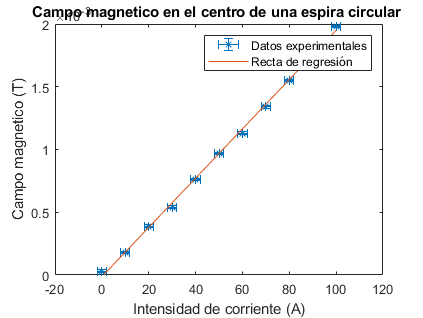


%Graficas 

% 1) datos en el centro plus recta de regresion

errpos= 2*ones(1,length(I1));
errneg= errpos;
errpos2= 0.01*10^-3*ones(1,length(I1));
errneg2= errpos2;

errorbar(I1,Bexp*10^-3,errneg2,errpos2,errneg,errpos,'*')
hold on 
plot(xint,y1)
title('Campo magnetico en el centro de una espira circular ')
xlabel('Intensidad de corriente (A)')
ylabel('Campo magnetico (T)')
legend('Datos experimentales', 'Recta de regresión')




% 2) Eje de la espira 
figure

x=-5:5

x =     -5    -4    -3    -2    -1     0     1     2     3     4     5


Bexp2=10^-3*[0.14,0.21,0.35,0.58,0.82,0.94,0.83,0.57,0.35,0.21,0.14]

Bexp2 = 1.0e-03 *

    0.1400    0.2100    0.3500    0.5800    0.8200    0.9400    0.8300    0.5700    0.3500    0.2100    0.1400



errpos= 0.1*ones(1,length(x));  
errneg= errpos;
errpos2= 0.01*10^-3*ones(1,length(x));
errneg2= errpos2;

errorbar(x,Bexp2,errneg2,errpos2,errneg,errpos,'*')
hold on 

e1=Bteo1+DBteo1

e1 =     0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010    0.0010


e2= Bteo1-DBteo1

e2 = 1.0e-03 *

    0.1420    0.1482    0.1548    0.1617    0.1689    0.1766    0.1847    0.1932    0.2022    0.2116    0.2216    0.2321    0.2431    0.2548    0.2670    0.2799    0.2935    0.3078    0.3228    0.3386    0.3551    0.3724    0.3906    0.4095    0.4293    0.4499    0.4714    0.4936    0.5166    0.5404    0.5648    0.5898    0.6153    0.6413    0.6675    0.6939    0.7202    0.7463    0.7720    0.7970    0.8211    0.8440    0.8655    0.8853    0.9031    0.9186    0.9317    0.9422    0.9498    0.9544


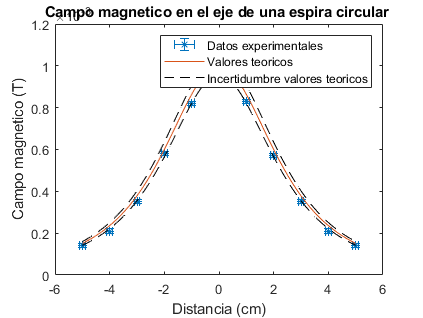


plot(xteo*100,Bteo1,xteo*100,e1,'--k',xteo*100,e2,'--k')

title('Campo magnetico en el eje de una espira circular ')
xlabel('Distancia (cm)')
ylabel('Campo magnetico (T)')
legend('Datos experimentales', 'Valores teoricos', 'Incertidumbre valores teoricos')





% 3) Eje conductor rectilineo

figure

Bexp3=10^-3*[0.21,0.24,0.33,0.44,0.53,0.72,1.05,1.07,0.74,0.55,0.45,0.31,0.23,0.19]

Bexp3 =     0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0011    0.0011    0.0007    0.0006    0.0005    0.0003    0.0002    0.0002


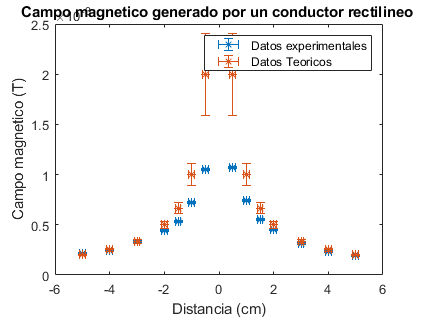


errpos= 0.1*ones(1,length(x2));  
errneg= errpos;
errpos2= 0.01*10^-3*ones(1,length(x2));
errneg2= errpos2;

errorbar(x2*100,Bexp3,errneg2,errpos2,errneg,errpos,'*')
hold on 


errpos= 0.1*ones(1,length(x2));  
errneg= errpos;
errorbar(x2*100,abs(Bteo2),DBteo2,DBteo2,errneg,errpos,'*')


title('Campo magnetico generado por un conductor rectilineo ')
xlabel('Distancia (cm)')
ylabel('Campo magnetico (T)')
legend('Datos experimentales', 'Datos Teoricos')